# Solución Puntos

## P5.3

P5Considerando el robot asignado, construya el modelo del robot utilizando RST

!) asignación sistemas de coordenadas

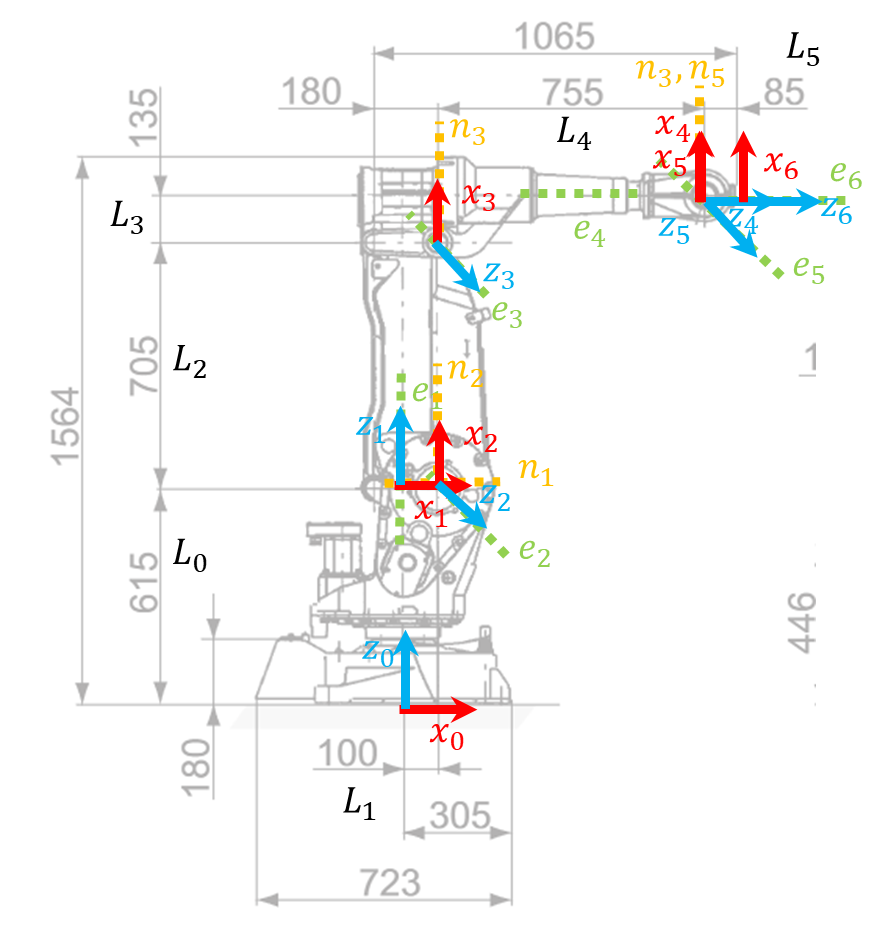

2) Parámetros DHmod

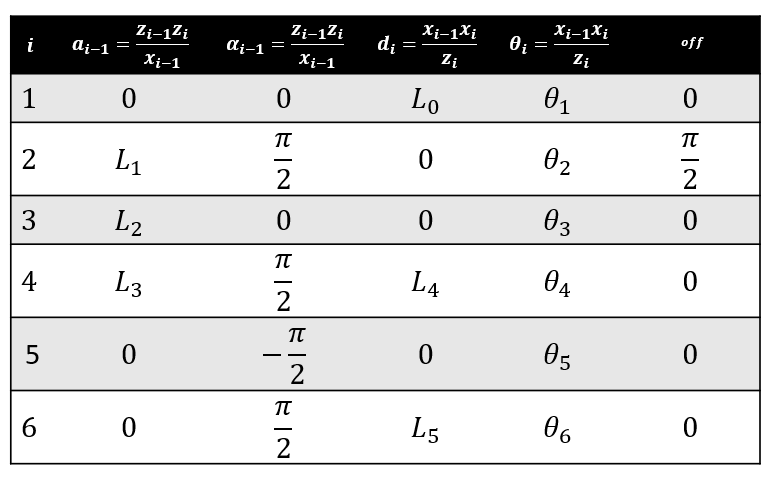

3) Usando Robotics System Toolbox, se obtiene el modelo de la siguiente manera

- Usando cuerpos rígidos

clear all;clf;clc;

robot = rigidBodyTree('DataFormat','column','MaxNumBodies',7);

L0 = 0.615;
L1 = 0.1;
L2 = 0.705;
L3 = 0.135;
L4 = 0.755;
L5 = 0.085;

% Se agrega Eslabón0 - Articulación0
body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,trvec2tform([0 0 0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'base');

% Se agrega Eslabón1 - Articulación1
body = rigidBody('link2');
joint = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint, trvec2tform([0,0,L0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link1');

% Se agrega Eslabón2 - Articulación2
body = rigidBody('link3');
joint = rigidBodyJoint('joint3','revolute');
setFixedTransform(joint, trvec2tform([L1,0,0])*eul2tform([pi/2 0 pi/2],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link2');

% Se agrega Eslabón3 - Articulación3
body = rigidBody('link4');
joint = rigidBodyJoint('joint4','revolute');
setFixedTransform(joint, trvec2tform([L2,0,0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link3');

% Se agrega Eslabón4 - Articulación4
body = rigidBody('link5');
joint = rigidBodyJoint('joint5','revolute');
setFixedTransform(joint, trvec2tform([L3,-L4,0])*eul2tform([pi/2 0 0],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link4');


% Se agrega Eslabón5 - Articulación5
body = rigidBody('link6');
joint = rigidBodyJoint('joint6','revolute');
setFixedTransform(joint, trvec2tform([0,0,0])*eul2tform([-pi/2 0 0],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link5');

% Se agrega Eslabón efector final
body = rigidBody('link7');
joint = rigidBodyJoint('joint7','revolute');
setFixedTransform(joint, trvec2tform([0,-L5,0])*eul2tform([pi/2 0 0],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link6');

show(robot)

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


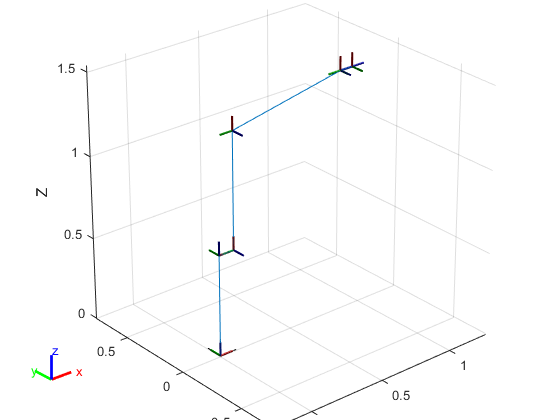

axis auto

view([-40.37 26.07])

- Usando matriz DHmod

dhparams = [0       0       L0      0;
            L1    pi/2       0   pi/2;
            L2      0        0      0;
            L3    pi/2      L4      0;
            0    -pi/2       0      0;
            0     pi/2      L5      0];    


robot2 = rigidBodyTree;
bodies = cell(6,1);
joints = cell(6,1);
%trotx(alpha)*transl(a,0,0)*trotz(theta_j)*transl(0,0,d_j)
for i = 1:6
    bodies{i} = rigidBody(['body' num2str(i)]);
    joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
    if dhparams(i,4)~= 0
        disp('its working')
        %trvec2tform([0,-L5,0])*eul2tform([pi/2 0 0],'XYZ'))
        T1 = eul2tform([dhparams(i,2) 0 0],'XYZ')*trvec2tform([dhparams(i,1) 0 0]);
        T2 = eul2tform([0 0 dhparams(i,4)],'XYZ')*trvec2tform([0 0 dhparams(i,3)]);
        setFixedTransform(joints{i},T1*T2 );
    else
        setFixedTransform(joints{i},dhparams(i,:),"mdh");
    end
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot2,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot2,bodies{i},bodies{i-1}.Name)
    end
end

its working



showdetails(robot2)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


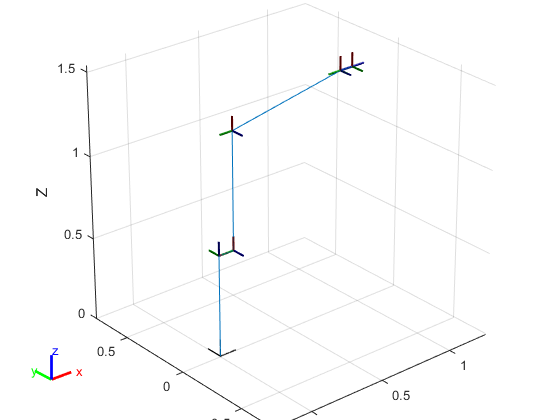

show(robot2);
axis auto
view([-40.37 26.07])